class1 = 'TURMER';
class2 = 'LUSMEG';

[TURMER_train40,TURMER_trainFs40] = createSequences(class1,"train","MaxSamplesPerBird",40);
[LUSMEG_train40,LUSMEG_trainFs40] = createSequences(class2,"train","MaxSamplesPerBird",40);

[XTrain, YTrain] = createFeatureCells(TURMER_train40,LUSMEG_train40,class1,class2);
XTrainFs = vertcat(TURMER_trainFs40,LUSMEG_trainFs40);

[TURMER_test40,TURMER_testFs40] = createSequences(class1,"test","MaxSamplesPerBird",40);
[LUSMEG_test40,LUSMEG_testFs40] = createSequences(class2,"test","MaxSamplesPerBird",40);

[XTest, YTest] = createFeatureCells(TURMER_test40,LUSMEG_test40,class1,class2);
XTestFs = vertcat(TURMER_testFs40,LUSMEG_testFs40);

c = cvpartition(size(XTrain,1),'KFold',7);
opts = struct('CVPartition',c,'AcquisitionFunctionName','expected-improvement-plus');

gtccEvalCell = {};

### Experiment 1: default / control

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |     0.25314 |       226.6 |     0.25314 |     0.25314 |       7.0702 |
|    2 | Best   |     0.20893 |      21.342 |     0.20893 |     0.21192 |    0.0020042 |
|    3 | Accept |     0.24187 |      60.476 |     0.20893 |     0.20893 |      0.21826 |
|    4 | Accept |     0.34547 |      240.57 |     0.20893 |     0.25599 |       220.66 |
|    5 | Accept |     0.20893 |      21.528 |     0.20893 |     0.20893 |    0.0020037 |
|    6 | Accept |     0.21023 |      23.594 |     0.20893 |     0.20893 |    0.0031832 |
|    7 | Accept |     0.21283 |      23.491 |     0.20893 |     0.20898 |    0.0010008 |
|    8 | Accept |    

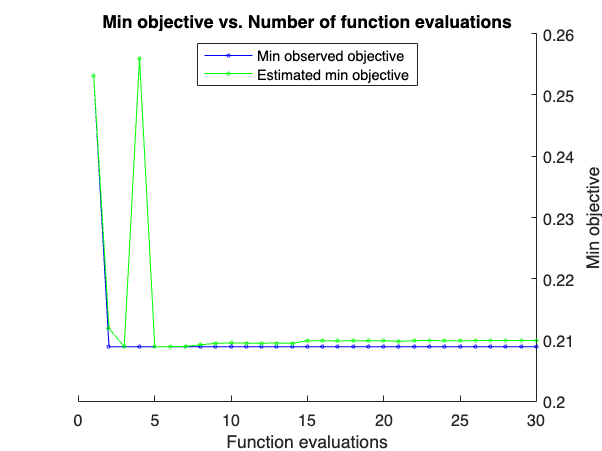

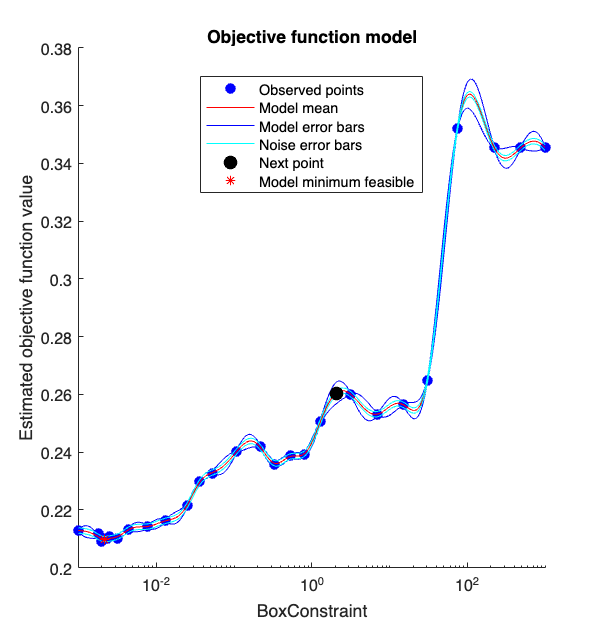


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 2951.2881 seconds
Total objective function evaluation time: 2904.6159

Best observed feasible point:
    BoxConstraint
    _____________

      0.0020042  

Observed objective function value = 0.20893
Estimated objective function value = 0.21005
Function evaluation time = 21.342

Best estimated feasible point (according to models):
    BoxConstraint
    _____________

      0.0021091  

Estimated objective function value = 0.20992
Estimated function evaluation time = 21.5212



XTrainGtcc1 = cellfun(@(a,b) extractGtcc(a,b),XTrain,XTrainFs,"UniformOutput",false);
XTrainGtcc1 = cell2Matrix(XTrainGtcc1);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.47984 |      35.053 |     0.47984 |     0.47984 |    0.0040613 |        807.9 |
|    2 | Accept |     0.47984 |      35.351 |     0.47984 |     0.47984 |       2.2457 |     0.011412 |
|    3 | Accept |     0.47984 |      39.244 |     0.47984 |     0.47984 |    0.0080016 |      0.16391 |
|    4 | Best   |    0.049848 |      14.002 |    0.049848 |    0.049938 |       7.6023 |       39.111 |
|    5 | Best   |    0.035977 |      14.096 |    0.035977 |    0.036314 |       21.776 |       35.127 |
|    6 | Accept |     0.47984 |      33.542 |    0.035977 |    0

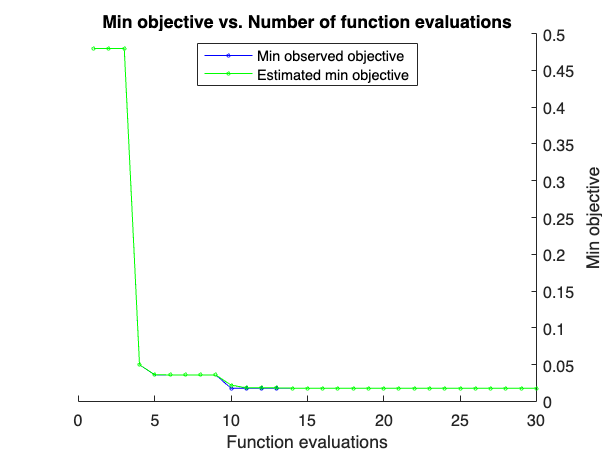

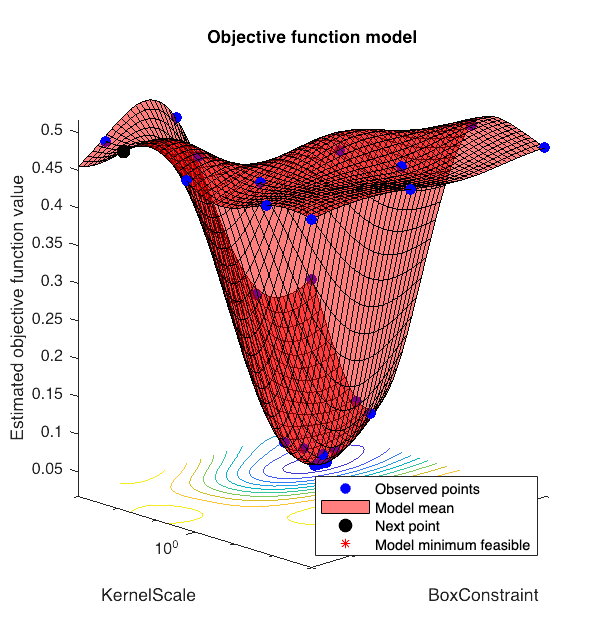


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 870.151 seconds
Total objective function evaluation time: 825.1987

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       32.048          17.909   

Observed objective function value = 0.017772
Estimated objective function value = 0.017829
Function evaluation time = 18.1473

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       32.048          17.909   

Estimated objective function value = 0.017829
Estimated function evaluation time = 19.3115



rbfMfcc1 =   ClassificationSVM
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [TURMER    LUSMEG]
                       ScoreTransform: 'none'
                      NumObservations: 2307
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                                Alpha: [1100×1 double]
                                 Bias: 1.0961
                     KernelParameters: [1×1 struct]
                       BoxConstraints: [2307×1 double]
                      ConvergenceInfo: [1×1 struct]
                      IsSupportVector: [2307×1 logical]
                               Solver: 'SMO'


  Properties, Methods


linearGtcc1 = fitcsvm(XTrainGtcc1,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0021091);

rbfGtcc1 = fitcsvm(XTrainGtcc1,YTrain,'KernelFunction','rbf','BoxConstraint',32.048,'KernelScale',17.909);

XTestGtcc1 = cellfun(@(a,b) extractGtcc(a,b),XTest,XTestFs,"UniformOutput",false);
XTestGtcc1 = cell2Matrix(XTestGtcc1);

rbf1 = generateEvaluationCell('rbf',1,rbfGtcc1,XTestGtcc1,YTest);
linear1 = generateEvaluationCell('linear',1,linearGtcc1,XTestGtcc1,YTest);
gtccEvalCell = [gtccEvalCell;rbf1;linear1];

### Experiment 2: 100 - 7000

XTrainGtcc2 = cellfun(@(a,b) extractGtcc(a,b,"MinFreq",100,"MaxFreq",7000),XTrain,XTrainFs,"UniformOutput",false);
XTrainGtcc2 = cell2Matrix(XTrainGtcc2);

linearGtcc2 = fitcsvm(XTrainGtcc2,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0021091);
rbfGtcc2 = fitcsvm(XTrainGtcc2,YTrain,'KernelFunction','rbf',"BoxConstraint",244.21,"KernelScale",15.139);

XTestGtcc2 = cellfun(@(a,b) extractGtcc(a,b,"MinFreq",100,"MaxFreq",7000),XTest,XTestFs,"UniformOutput",false);
XTestGtcc2 = cell2Matrix(XTestGtcc2);

rbf2 = generateEvaluationCell('rbf',2,rbfGtcc2,XTestGtcc2,YTest);
linear2 = generateEvaluationCell('linear',2,linearGtcc2,XTestGtcc2,YTest);
gtccEvalCell = [gtccEvalCell;rbf2;linear2];

### Experiment 3: 50 - 10000

XTrainGtcc3 = cellfun(@(a,b) extractGtcc(a,b,"MinFreq",50,"MaxFreq",10000),XTrain,XTrainFs,"UniformOutput",false);
XTrainGtcc3 = cell2Matrix(XTrainGtcc3);

linearGtcc3 = fitcsvm(XTrainGtcc3,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0021091);
rbfGtcc3 = fitcsvm(XTrainGtcc3,YTrain,'KernelFunction','rbf',"BoxConstraint",254,"KernelScale",14.211);

XTestGtcc3 = cellfun(@(a,b) extractGtcc(a,b,"MinFreq",50,"MaxFreq",10000),XTest,XTestFs,"UniformOutput",false);
XTestGtcc3 = cell2Matrix(XTestGtcc3);

rbf3 = generateEvaluationCell('rbf',3,rbfGtcc3,XTestGtcc3,YTest);
linear3 = generateEvaluationCell('linear',3,linearGtcc3,XTestGtcc3,YTest);
gtccEvalCell = [gtccEvalCell;rbf3;linear3];

### Experiment 4: 400 - 6000

XTrainGtcc4 = cellfun(@(a,b) extractGtcc(a,b,"MinFreq",400,"MaxFreq",6000),XTrain,XTrainFs,"UniformOutput",false);
XTrainGtcc4 = cell2Matrix(XTrainGtcc4);

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.47984 |      49.546 |     0.47984 |     0.47984 |        961.7 |     0.011536 |
|    2 | Best   |    0.039879 |      26.805 |    0.039879 |    0.068008 |       765.97 |       10.739 |
|    3 | Accept |     0.47984 |      35.743 |    0.039879 |    0.039923 |     0.017492 |       0.1462 |
|    4 | Accept |     0.47984 |      38.161 |    0.039879 |    0.073283 |    0.0025308 |       116.25 |
|    5 | Accept |    0.045947 |      25.601 |    0.039879 |    0.040073 |       548.39 |       10.004 |
|    6 | Accept |    0.057651 |      15.774 |    0.039879 |    0

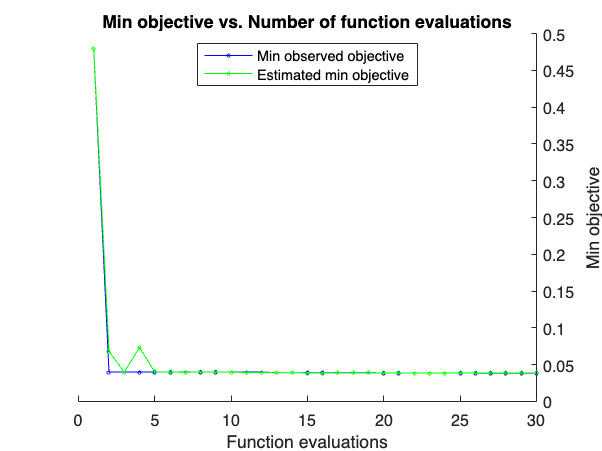

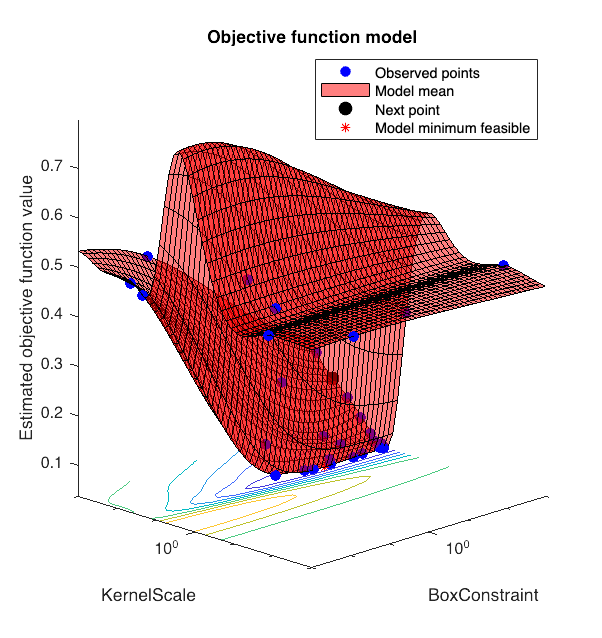


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 827.9892 seconds
Total objective function evaluation time: 788.1941

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       35.446          11.659   

Observed objective function value = 0.038145
Estimated objective function value = 0.037981
Function evaluation time = 23.2299

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       839.21          12.299   

Estimated objective function value = 0.038768
Estimated function evaluation time = 23.2734



linearGtcc4 = fitcsvm(XTrainGtcc4,YTrain,'KernelFunction','linear','Standardize',false,'BoxConstraint',0.0021091);

rbfGtcc4 = fitcsvm(XTrainGtcc4,YTrain,'KernelFunction','rbf',"BoxConstraint",839.21,"KernelScale",12.999);

XTestGtcc4 = cellfun(@(a,b) extractGtcc(a,b,"MinFreq",400,"MaxFreq",6000),XTest,XTestFs,"UniformOutput",false);
XTestGtcc4 = cell2Matrix(XTestGtcc4);

rbf4 = generateEvaluationCell('rbf',4,rbfGtcc4,XTestGtcc4,YTest);
linear4 = generateEvaluationCell('linear',4,linearGtcc4,XTestGtcc4,YTest);
gtccEvalCell = [gtccEvalCell;rbf4;linear4];

gtccExperimentBarAUCData = zeros(4,2);
gtccExperimentBarAccData = zeros(4,2);
for i = 1:(length(gtccEvalCell)/2)
    gtccExperimentBarAUCData(i,1) = gtccEvalCell{2*i,3};
    gtccExperimentBarAUCData(i,2) = gtccEvalCell{2*i-1,3};
    gtccExperimentBarAccData(i,1) = gtccEvalCell{2*i,4};
    gtccExperimentBarAccData(i,2) = gtccEvalCell{2*i-1,4};
end

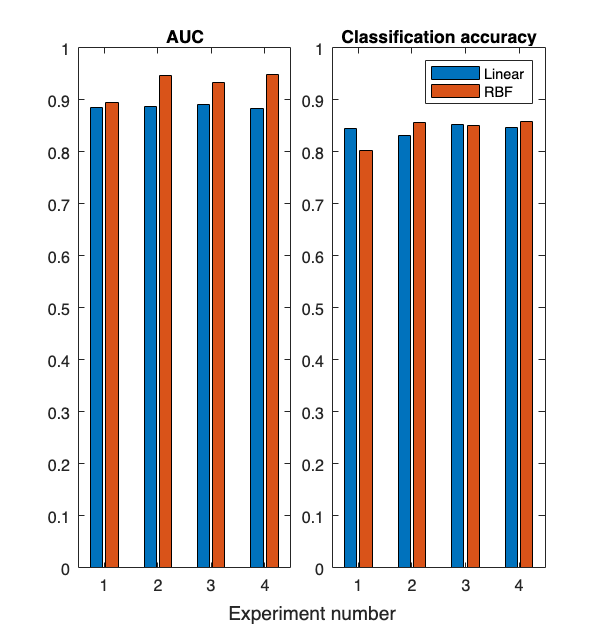

t = tiledlayout(1,2);
t.TileSpacing = "compact";

nexttile
bar(gtccExperimentBarAUCData)
title('AUC')

nexttile
bar(gtccExperimentBarAccData)
ylim([0 1])
title('Classification accuracy')

legend({'Linear','RBF'})

xlabel(t, 'Experiment number')

function matrix = cell2Matrix(cell)
matrix = zeros(numel(cell),numel(cell{1}));
for row = 1:numel(cell)
matrix(row,:) = cell{row};
end
end

function gtccFeature = extractGtcc(signal,fs,nva)
arguments
signal
fs
nva.MinFreq = 50
nva.MaxFreq = 'max'
end
if isstring(nva.MaxFreq) && nva.MaxFreq == "max"
    maxFreq = fs/2;
else
    maxFreq = nva.MaxFreq;
end
freqRange = [nva.MinFreq maxFreq];
[coeffs, delta, ddelta, ~] = gtcc(signal,fs,"FrequencyRange",freqRange);
gtccFeature = [coeffs(:);delta(:);ddelta(:)];
end

function evalCell = generateEvaluationCell(type,experimentNum,model,XTest,YTest)
[auc,accuracy,ROCX,ROCY] = evaluateSVM(model,XTest,YTest);
evalCell = {type,experimentNum,auc,accuracy,ROCX,ROCY};
end